# Density Scatter Chart Examples

Create some random normal data to test the chart

x=randn(1000,1);
y=randn(1000,1);

Create a chart where color varies with density

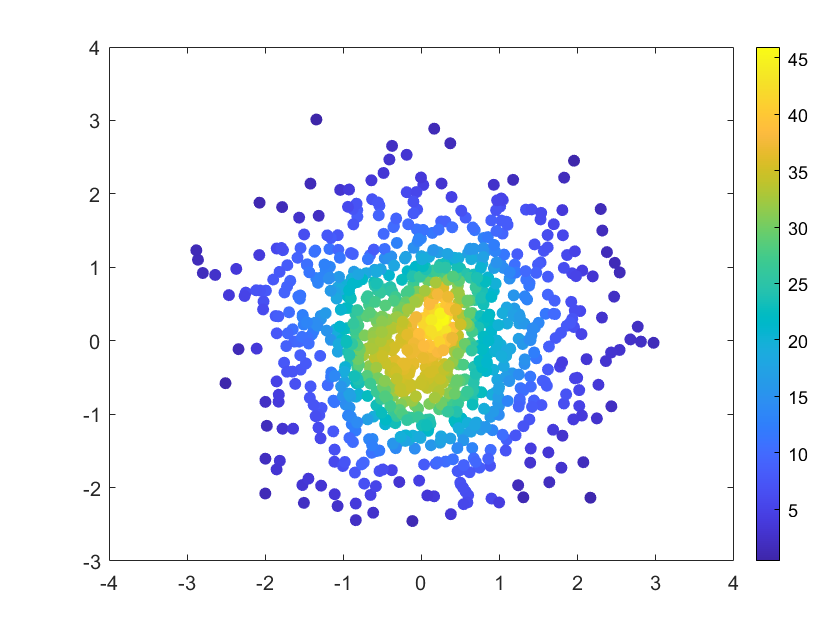

densityScatterChart(x,y);

You can set properties using name value pairs

Create a chart where transparency varies with density:

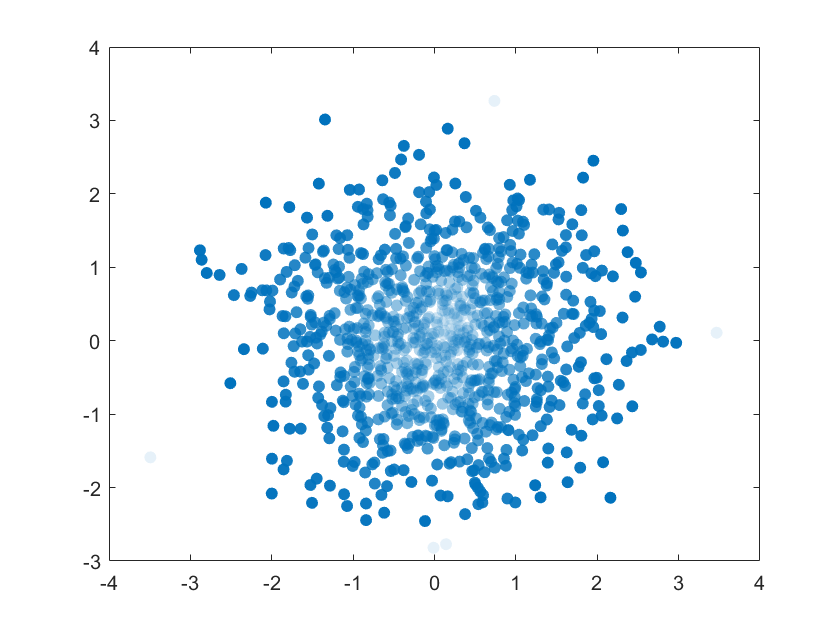

densityScatterChart(x, y, 'UseColor', false, 'UseAlpha', true);

Specify a title:

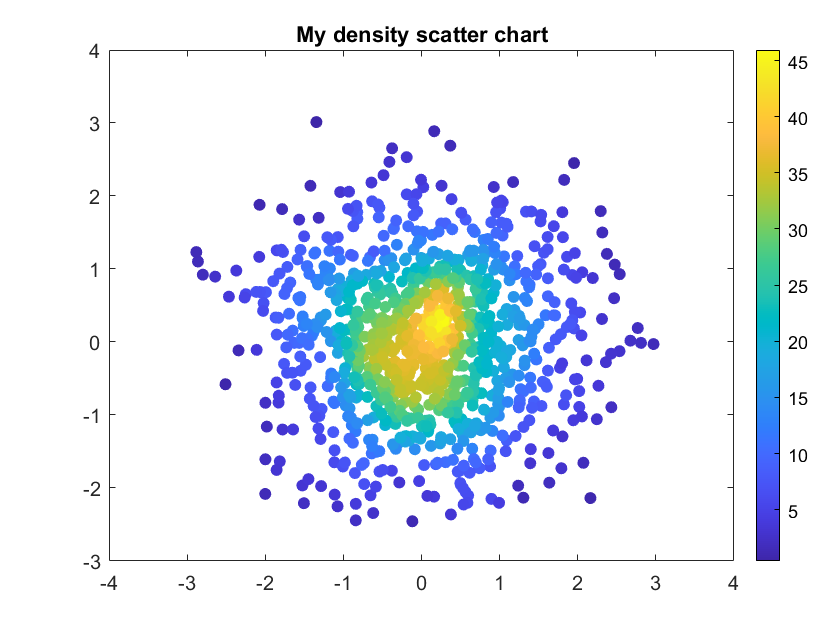

densityScatterChart(x, y, "Title", "My density scatter chart");

You can also set properties after making the chart:

d=densityScatterChart(x, y);

Make a steeper density view

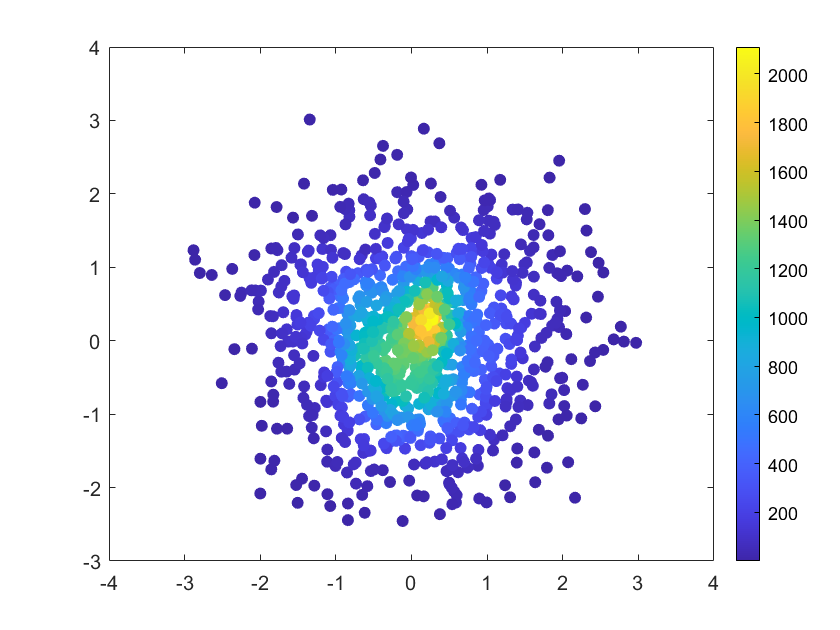

d.DensityExponent = 2;

Use alpha, but make it a subtle effect by using a small range:

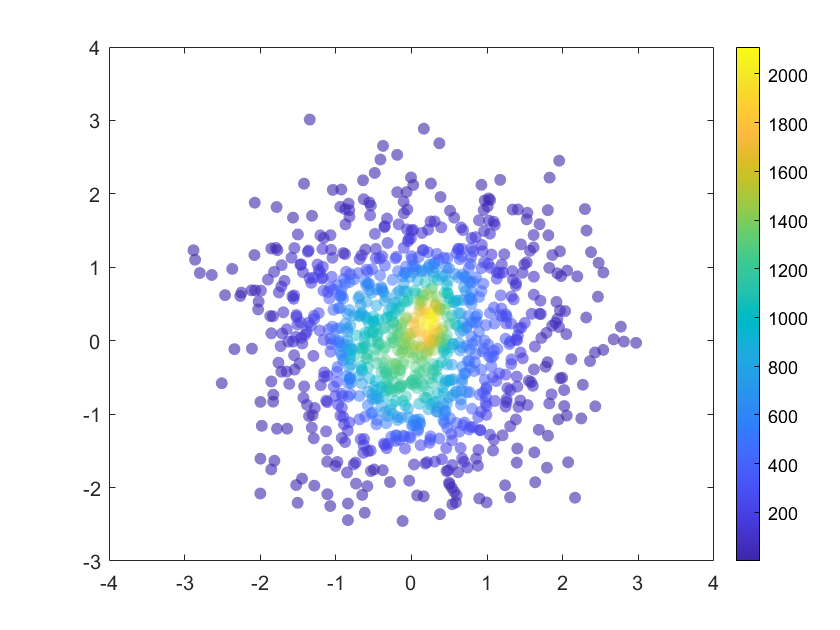

d.UseAlpha = "on";
d.AlphaRange = [.3 .6];

Use a custom density measure, that corresponds to the distance to the mean point:

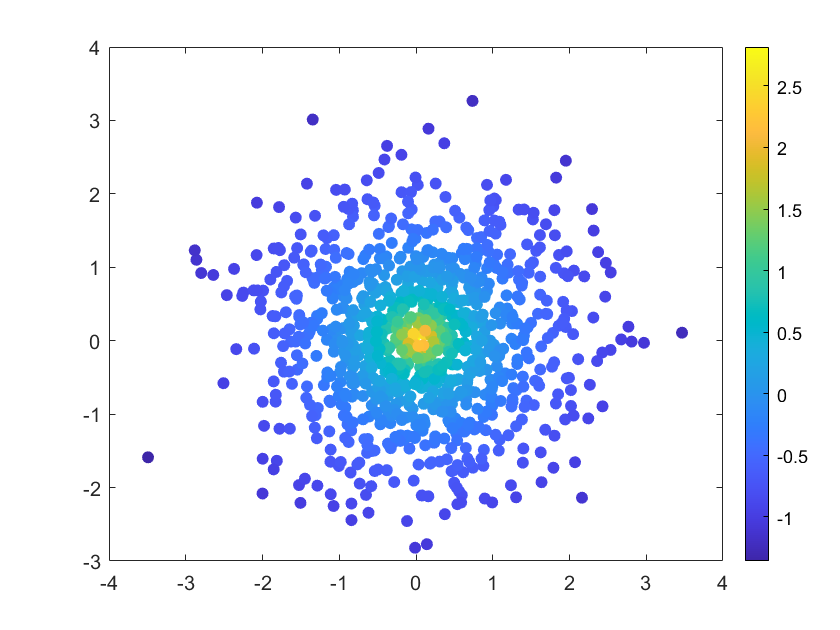

dfunc = @(x,y) log(1./sqrt((x-mean(x)).^2 + (y-mean(x)).^2));
d=densityScatterChart(x, y, "DensityMethod", dfunc);

The custom method looks similar to density with normal data, but looks distinct with random uniform data

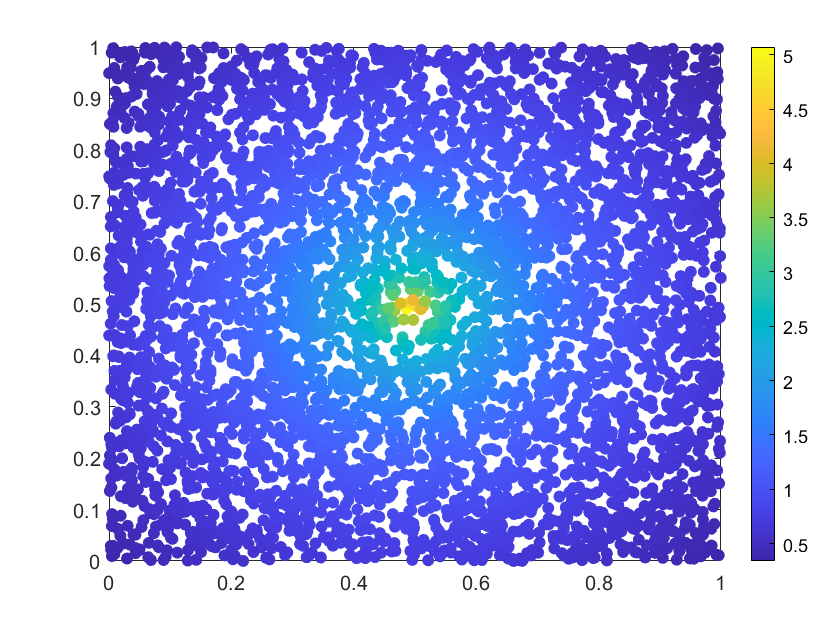

d=densityScatterChart(rand(1,5000), rand(1,5000), "DensityMethod", dfunc);

`Change the color limits and colormap:`

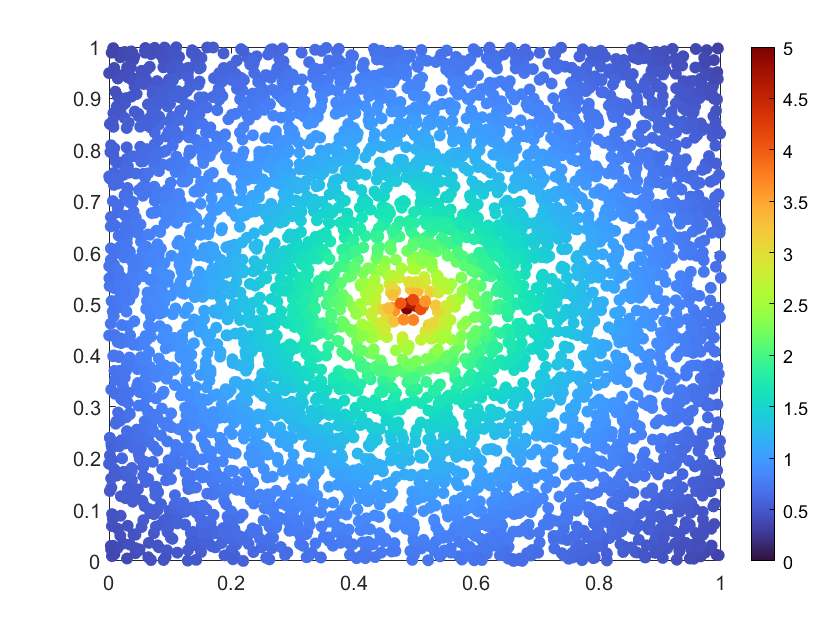

d.CLim = [0 5];
colormap turbo